clc; clear; close all;

%% -------------------------------
% 1. Input time-series signal
%% -------------------------------
n = 140;
t = linspace(0,1,n);
x = sin(2*pi*5*t) + 0.2*randn(1,n);

%% -------------------------------
% 2. Adaptive kernel (statistics-based)
%% -------------------------------
mu = mean(x);
sigma = std(x);
K = [mu - 2*sigma, mu, mu + 2*sigma];
k_len = length(K);

%% -------------------------------
% 3. Toeplitz matrix construction
%    Rows = kernel length
%    Columns = signal length
%% -------------------------------
first_col = [x(1), zeros(1, k_len-1)]';
first_row = x;
T = toeplitz(first_col, first_row);

size(T)

ans =      3   140


size(K)

ans =      1     3


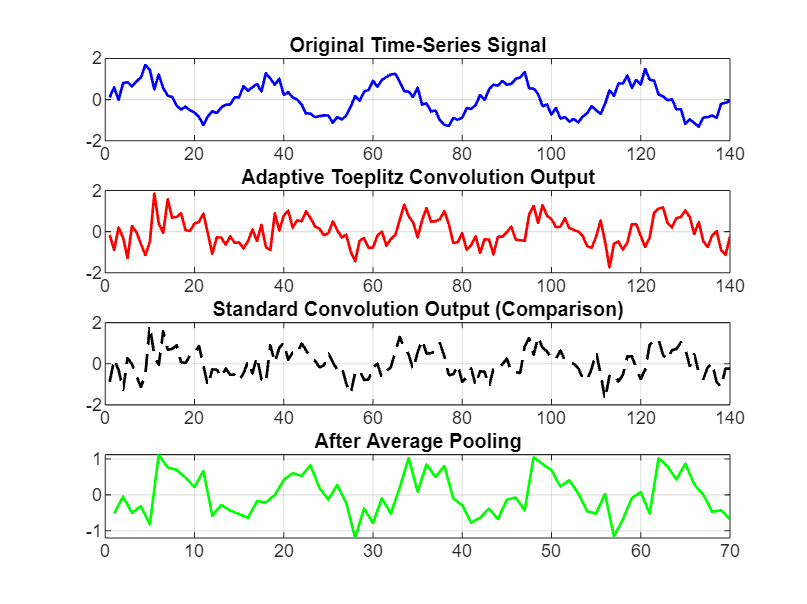


% Dimension check (important)
assert(size(T,1) == k_len, 'Toeplitz rows must equal kernel length');

%% -------------------------------
% 4. Toeplitz convolution (matrix form)
%% -------------------------------
y_toeplitz = K * T;
y_toeplitz = y_toeplitz(1:n);

%% -------------------------------
% 5. Standard convolution (for comparison)
%% -------------------------------
y_standard = conv(x, K, 'same');

%% -------------------------------
% 6. Average pooling (stride = 2)
%% -------------------------------
y_pooled = (y_toeplitz(1:2:end-1) + y_toeplitz(2:2:end)) / 2;

%% -------------------------------
% 7. Visualization
%% -------------------------------
figure('Color','w');

subplot(4,1,1)
plot(x,'b','LineWidth',1.2)
title('Original Time-Series Signal')
grid on

subplot(4,1,2)
plot(y_toeplitz,'r','LineWidth',1.2)
title('Adaptive Toeplitz Convolution Output')
grid on

subplot(4,1,3)
plot(y_standard,'k--','LineWidth',1.2)
title('Standard Convolution Output (Comparison)')
grid on

subplot(4,1,4)
plot(y_pooled,'g','LineWidth',1.2)
title('After Average Pooling')
grid on


%% -------------------------------
% 8. Display results
%% -------------------------------
disp('Adaptive Toeplitz Convolution – Final Results')

Adaptive Toeplitz Convolution – Final Results


disp('--------------------------------------------')

--------------------------------------------


disp(['Signal Length            : ', num2str(n)])

Signal Length            : 140


disp(['Adaptive Kernel          : [', num2str(K), ']'])

Adaptive Kernel          : [-1.4409   -0.019141      1.4026]


disp(['Toeplitz Output Length   : ', num2str(length(y_toeplitz))])

Toeplitz Output Length   : 140


disp(['Pooled Output Length     : ', num2str(length(y_pooled))])

Pooled Output Length     : 70
